# exploring the Inspector scores

## load scores

global DEFAULT_MATFILE_DIR 
load([DEFAULT_MATFILE_DIR '/CJF_inspector_scores.mat']);


## Inspector scores (good)

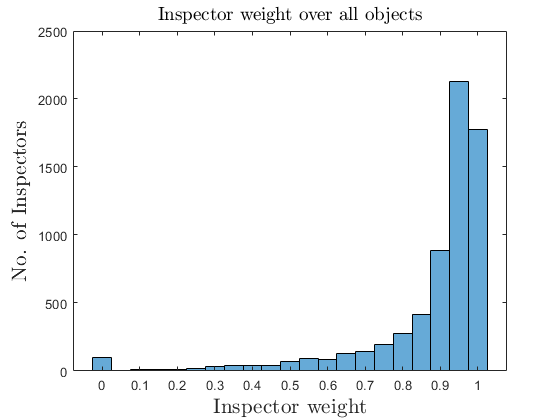

ll=-0.025:0.05:1.025;

figure

histogram(iscore.score,ll)
xlabelmine('Inspector weight');
ylabelmine('No. of Inspectors');
titlemine('Inspector weight over all objects');

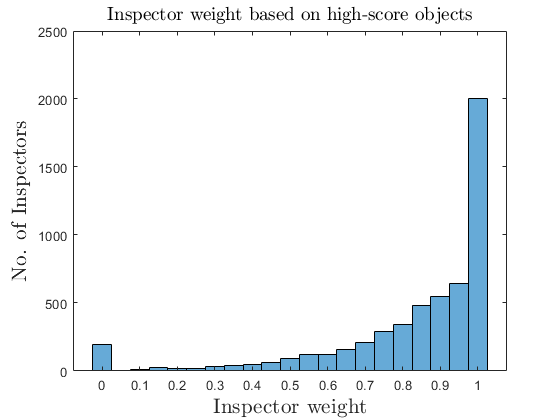


figure
histogram(iscoreHigh.score(iscoreHigh.ncls>0),ll)
xlabelmine('Inspector weight');
ylabelmine('No. of Inspectors');
titlemine('Inspector weight based on high-score objects');

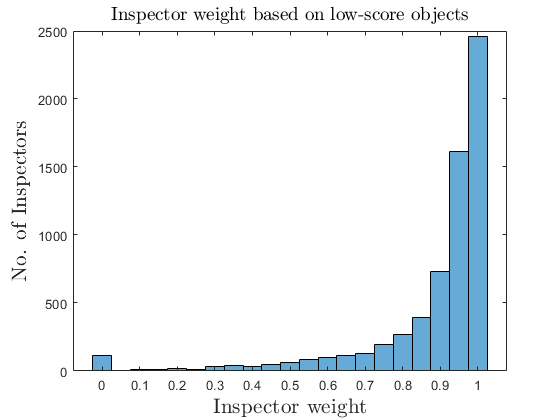


figure
histogram(iscoreLow.score(iscoreLow.ncls>0),ll)
xlabelmine('Inspector weight');
ylabelmine('No. of Inspectors');
titlemine('Inspector weight based on low-score objects');

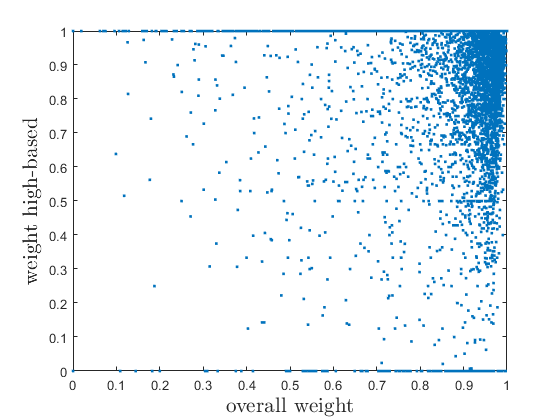

figure
plot(iscore.score,iscoreHigh.score,'.')

xlabelmine('overall weight');
ylabelmine('weight high-based' );

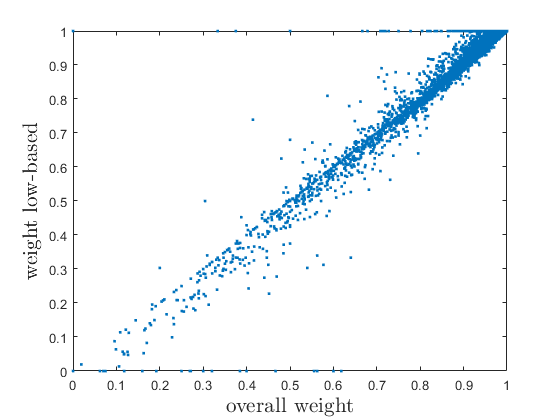


figure
plot(iscore.score,iscoreLow.score,'.')
xlabelmine('overall weight');
ylabelmine('weight low-based');

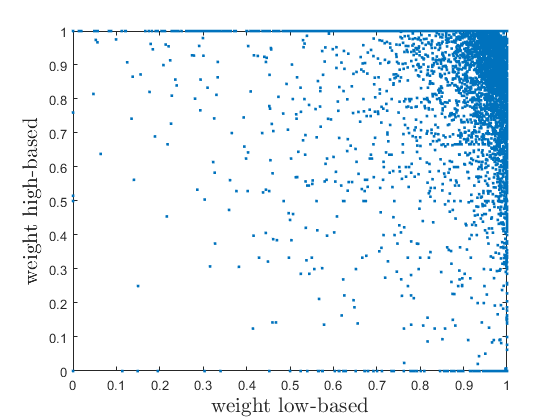


figure
plot(iscoreLow.score,iscoreHigh.score,'.')
ylabelmine('weight high-based' );
xlabelmine('weight low-based');

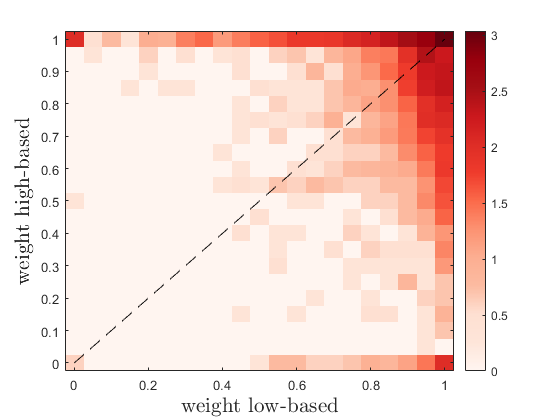


[bird, binsize, xl,yl]= histogram2d(iscoreLow.score,iscoreHigh.score,ones(size(iscoreHigh.score)),'len',21);
bbird=squeeze(bird(:,:,1));
figure
imagesc(xl,yl,log10(bbird))
hold on
plot([0 1],[0 1],'--k')
colormap(brewermap(256,'Reds'))
set(gca,'ydir','normal')
hb=colorbar;
ylabelmine('weight high-based' );
xlabelmine('weight low-based');

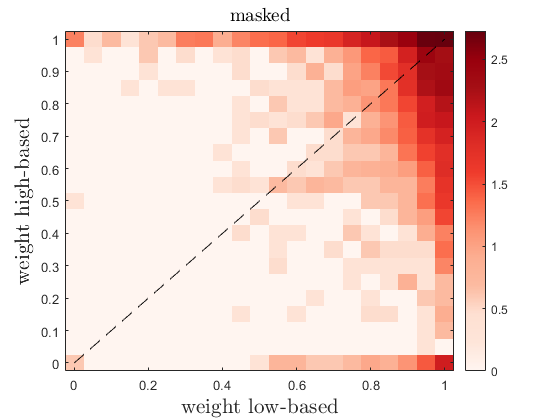



figure

msk=iscoreLow.ncls>0 & iscoreHigh.ncls>0;

[bird, binsize, xl,yl]= histogram2d(iscoreLow.score(msk),iscoreHigh.score(msk),ones(size(iscoreHigh.score(msk))),'len',21);
bbird=squeeze(bird(:,:,1));
figure
imagesc(xl,yl,log10(bbird))
hold on
plot([0 1],[0 1],'--k')
colormap(brewermap(256,'Reds'))
set(gca,'ydir','normal')
hb=colorbar;
ylabelmine('weight high-based' );
xlabelmine('weight low-based');


% plot(iscoreLow.score(msk),iscoreHigh.score(msk),'.')
% ylabelmine('score high' );
% xlabelmine('score low');
titlemine('masked');

## atempt at combining low and high scores

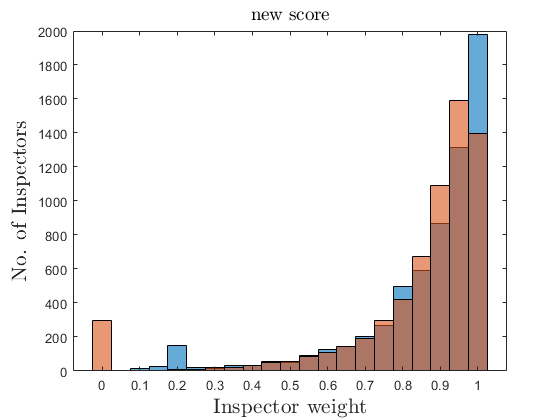


msk=true(size(iscoreHigh.score));
newScore1=0.8.*iscoreHigh.score(msk)+0.2.*iscoreLow.score(msk);
newScore2=sqrt(iscoreHigh.score(msk).*iscoreLow.score(msk));
newScore3=2.*(1./iscoreHigh.score(msk)+1./iscoreLow.score(msk));


figure
histogram(newScore1,ll)
hold on
histogram(newScore2,ll)
%histogram(newScore3,ll)
xlabelmine('Inspector weight');
ylabelmine('No. of Inspectors');
titlemine('new score');

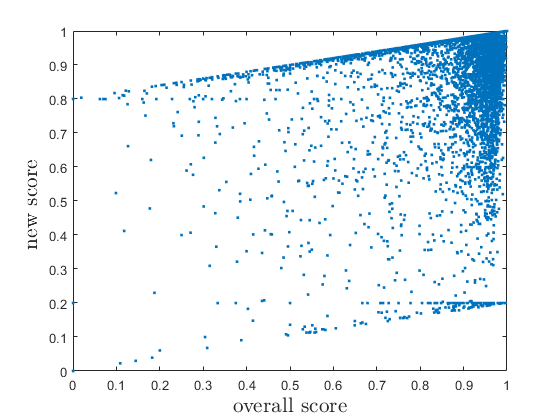




figure

plot(iscore.score(msk),newScore1,'.')
xlabelmine('overall score');
ylabelmine('new score ' );

## compare good scores to bad scores

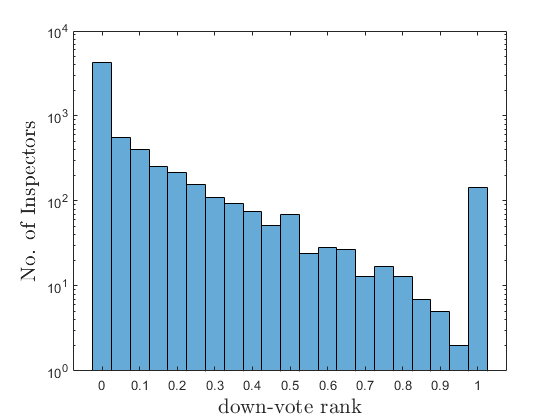

figure
histogram(badScore.downVoteScore,ll)
set(gca,'yscale','log')
xlabelmine('down-vote rank');
ylabelmine('No. of Inspectors');

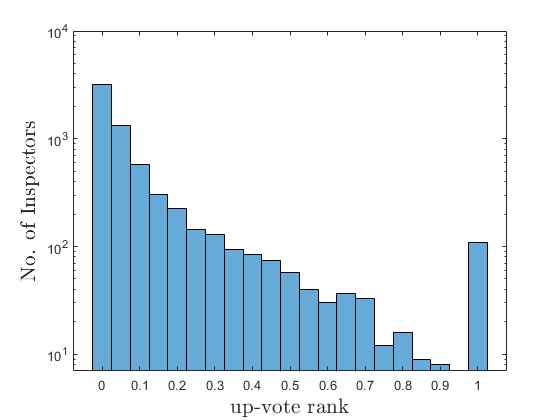

figure
histogram(badScore.upVoteScore,ll)
set(gca,'yscale','log')
xlabelmine('up-vote rank');
ylabelmine('No. of Inspectors');

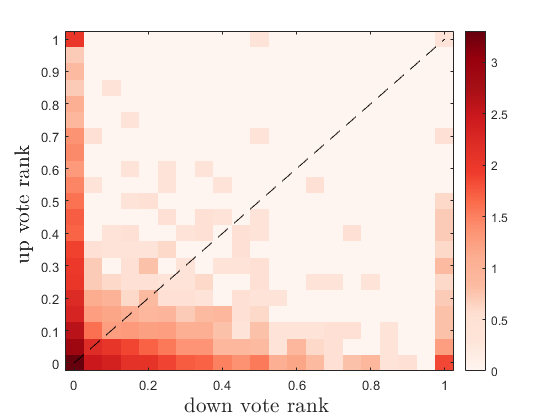



[bird, binsize, xl,yl]= histogram2d(badScore.downVoteScore,badScore.upVoteScore,ones(size(badScore.upVoteScore)),'len',21);
bbird=squeeze(bird(:,:,1));
figure
imagesc(xl,yl,log10(bbird))
hold on
plot([0 1],[0 1],'--k')
colormap(brewermap(256,'Reds'))
set(gca,'ydir','normal')
hb=colorbar;

xlabelmine('down vote rank ');
ylabelmine('up vote rank ');

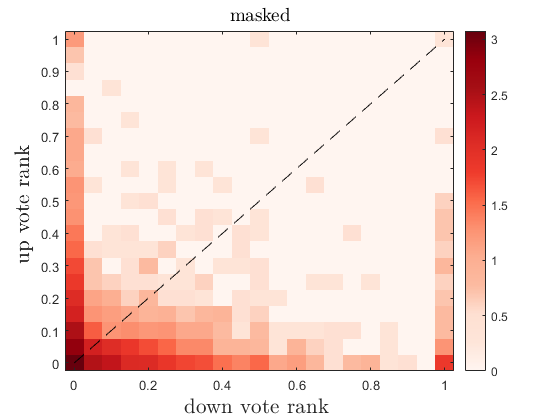



msk=badScore.upVoteNum>0 & badScore.downVoteNum>0;
[bird, binsize, xl,yl]= histogram2d(badScore.downVoteScore(msk),badScore.upVoteScore(msk),ones(size(badScore.upVoteScore(msk))),'len',21);
bbird=squeeze(bird(:,:,1));
figure
imagesc(xl,yl,log10(bbird))
hold on
plot([0 1],[0 1],'--k')
colormap(brewermap(256,'Reds'))
set(gca,'ydir','normal')
hb=colorbar;

xlabelmine('down vote rank ');
ylabelmine('up vote rank ');
titlemine('masked');

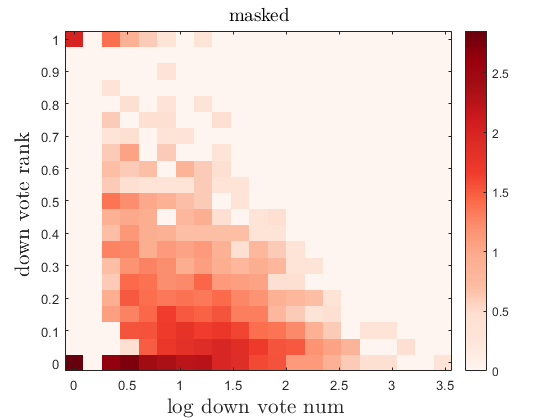


msk= badScore.downVoteNum>0;
[bird, binsize, xl,yl]= histogram2d(log10(badScore.downVoteNum(msk)),badScore.downVoteScore(msk),ones(size(badScore.downVoteScore(msk))),'len',21);
bbird=squeeze(bird(:,:,1));
figure
imagesc(xl,yl,log10(bbird))
hold on
%plot([0 1],[0 1],'--k')
colormap(brewermap(256,'Reds'))
set(gca,'ydir','normal')
hb=colorbar;

xlabelmine('log down vote num  ');
ylabelmine('down vote rank ');
titlemine('masked');

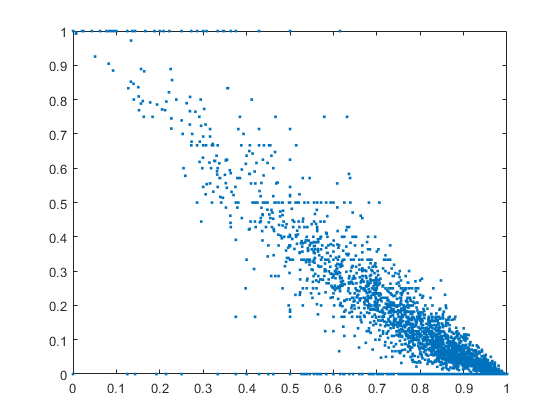






figure
plot(iscoreHigh.score,badScore.downVoteScore,'.')

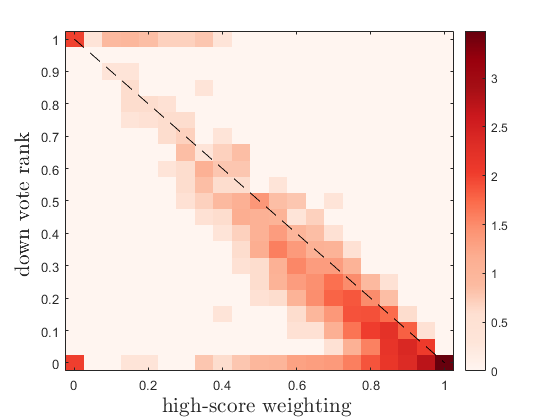


[bird, binsize, xl,yl]= histogram2d(iscoreHigh.score,badScore.downVoteScore,ones(size(badScore.upVoteScore)),'len',21);
bbird=squeeze(bird(:,:,1));
figure
imagesc(xl,yl,log10(bbird))
hold on
plot([0 1],[1 0],'--k')
colormap(brewermap(256,'Reds'))
set(gca,'ydir','normal')
hb=colorbar;

xlabelmine('high-score weighting ');
ylabelmine('down vote rank ');

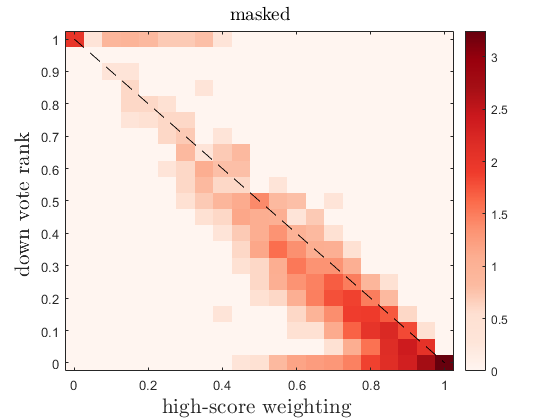





msk= badScore.downVoteNum>0 & iscoreHigh.ncls>0;
[bird, binsize, xl,yl]= histogram2d(iscoreHigh.score(msk),badScore.downVoteScore(msk),ones(size(badScore.upVoteScore(msk))),'len',21);
bbird=squeeze(bird(:,:,1));
figure
imagesc(xl,yl,log10(bbird))
hold on
plot([0 1],[1 0],'--k')
colormap(brewermap(256,'Reds'))
set(gca,'ydir','normal')
hb=colorbar;

xlabelmine('high-score weighting ');
ylabelmine('down vote rank ');
titlemine('masked');

## What is the down voting percentage ?

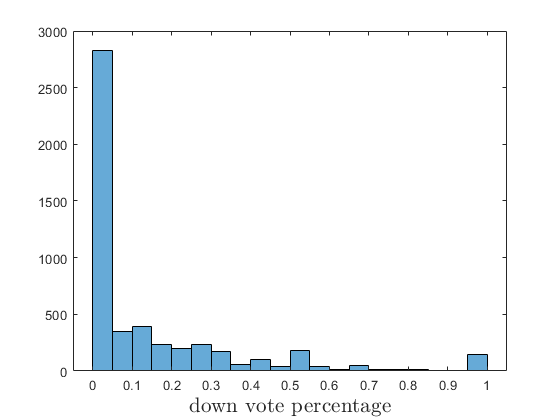

figure;
pp=badScore.downVote./badScore.downVoteNum;
histogram(pp)
xlabelmine('down vote percentage');

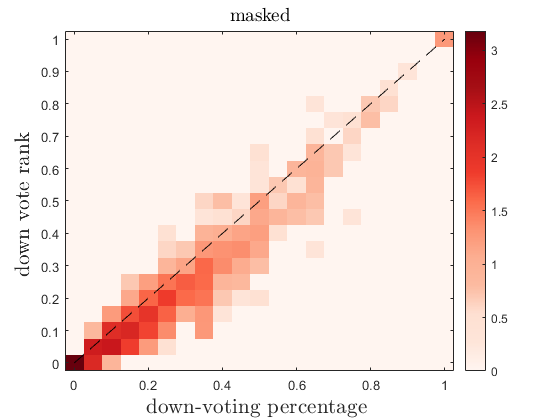



msk= badScore.downVoteNum>=3 ;
[bird, binsize, xl,yl]= histogram2d(pp(msk),badScore.downVoteScore(msk),ones(size(badScore.upVoteScore(msk))),'len',21);
bbird=squeeze(bird(:,:,1));
figure;
imagesc(xl,yl,log10(bbird))
hold on
plot([0 1],[0 1],'--k')
colormap(brewermap(256,'Reds'))
set(gca,'ydir','normal')
hb=colorbar;

xlabelmine('down-voting percentage ');
ylabelmine('down vote rank ');
titlemine('masked');

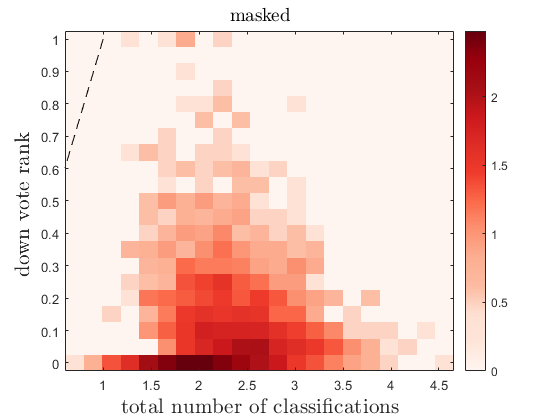


msk= iscore.ncls>0 & badScore.downVoteNum>=3 ;
[bird, binsize, xl,yl]= histogram2d(log10(iscore.ncls(msk)),badScore.downVoteScore(msk),ones(size(badScore.upVoteScore(msk))),'len',21);
bbird=squeeze(bird(:,:,1));
figure;
imagesc(xl,yl,log10(bbird))
hold on
plot([0 1],[0 1],'--k')
colormap(brewermap(256,'Reds'))
set(gca,'ydir','normal')
hb=colorbar;

xlabelmine('total number of classifications');
ylabelmine('down vote rank ');
titlemine('masked');

## What is the up voting percentage ?

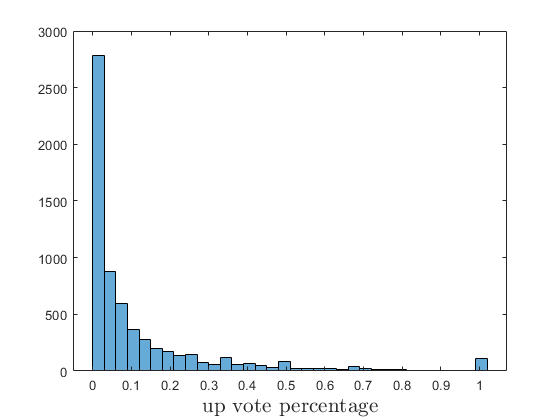

figure;
pp=badScore.upVote./badScore.upVoteNum;
histogram(pp)
xlabelmine('up vote percentage');

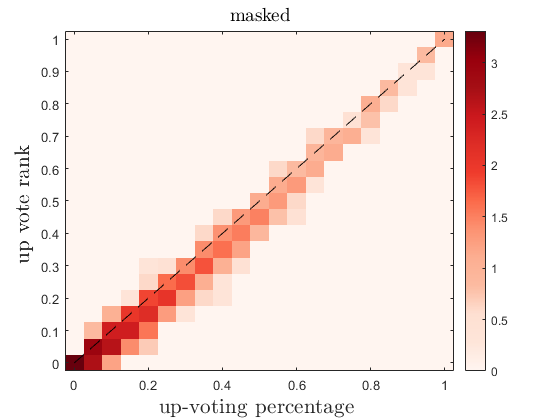



msk= badScore.upVoteNum>4 ;
[bird, binsize, xl,yl]= histogram2d(pp(msk),badScore.upVoteScore(msk),ones(size(badScore.upVoteScore(msk))),'len',21);
bbird=squeeze(bird(:,:,1));
figure;
imagesc(xl,yl,log10(bbird))
hold on
plot([0 1],[0 1],'--k')
colormap(brewermap(256,'Reds'))
set(gca,'ydir','normal')
hb=colorbar;

xlabelmine('up-voting percentage ');
ylabelmine('up vote rank ');
titlemine('masked');

## test out combination

## How dp the experts rank?

iexp(1)=find(GC.user_name.contains('zinger'));

Unable to resolve the name GC.user_name.contains.

iexp(2)=find(GC.user_name.contains('illepic'));
iexp(3)=find(GC.user_name.contains('rohr'));
iexp(4)=find(GC.user_name.contains('gandha'));
iexp(5)=find(GC.user_name.contains('dnels'));

GC.user_name(iexp)
GC.GroupCount(iexp)

iscore.score(iexp)
iscore.ncls(iexp)

iscoreHigh.score(iexp)
iscoreHigh.ncls(iexp)

iscoreLow.score(iexp)
iscoreLow.ncls(iexp)

badScore.upVoteScore(iexp)
badScore.upVote(iexp)
badScore.upVoteNum(iexp)
badScore.upVote(iexp)./badScore.upVoteNum(iexp)

badScore.downVoteScore(iexp)
badScore.downVote(iexp)
badScore.downVoteNum(iexp)